question 2

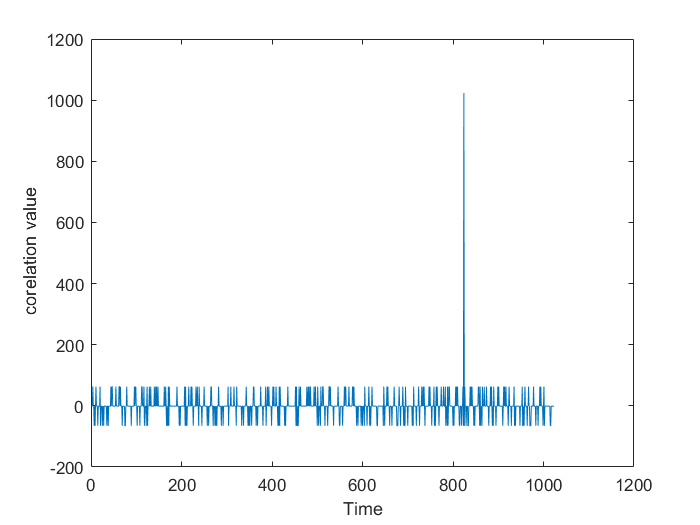

PRN8 = gps.code_generator(8,1);
PRN8_change_delay = gps.change(circshift(PRN8,200));
circular_arr = gps.circular_corr(PRN8_change_delay);
arr_output  = circular_arr * transpose(gps.change(PRN8));
t= linspace(1,1023,1023);
plot(t,arr_output);
ylabel(' corelation value');
xlabel('Time');

question 3

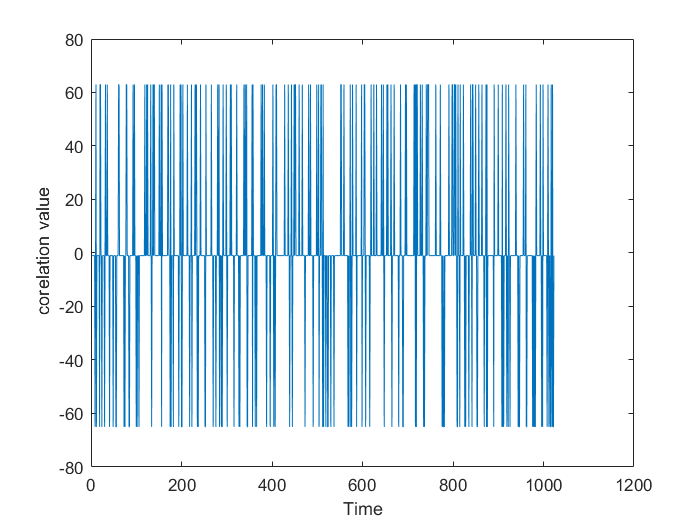

PRN8 = gps.code_generator(8,1);
PRN16 = gps.code_generator(16,1);
PRN8_change_transpose = transpose(gps.change(PRN8));
PRN16_change_delay = gps.change(circshift(PRN16,900));
circular_arr= gps.circular_corr(PRN16_change_delay);
arr_output  = circular_arr *  transpose(gps.change(PRN8));
t= linspace(1,1023,1023);

plot(t,arr_output);

ylabel(' corelation value');
xlabel('Time');

question 4

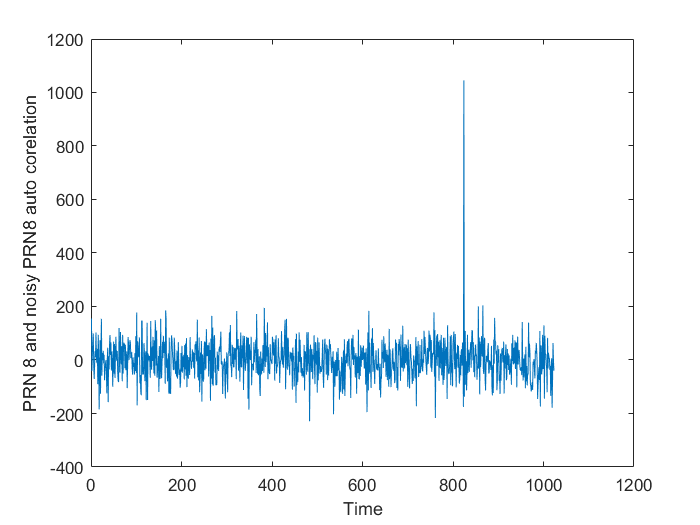

PRN8 = gps.code_generator(8,1);
PRN8_change_delay = gps.change(circshift(PRN8,200));
variance = 4;
W = sqrt(variance).*randn(1,size(PRN8_change_delay,2)); %Gaussian white noise W
PRN8_change_delay_noise = PRN8_change_delay + W; %Add the noise
circular_arr = gps.circular_corr(PRN8_change_delay_noise);
arr_output  = circular_arr * transpose(gps.change(PRN8));
t= linspace(1,1023,1023);
plot(t,arr_output);
ylabel('PRN 8 and noisy PRN8 auto corelation');
xlabel('Time');

question 5